clc; clear;
baby = imread("baby.jpg");
temp = imread("template.jpg");

% RGB to gray
baby_gray = rgbtogray(baby);
temp_gray = rgbtogray(temp);

%pad
[Height, Width] = size(temp_gray);
padWidth = round(Width / 2);
padHeight = round(Height / 2);
%进行填充
baby_padded = padarray(baby_gray,[padHeight, padWidth], 'symmetric');

%Convolution Operation for Square Difference Matching
result = zeros(size(baby_padded)-size(temp_gray)+1);
for i = 1:size(result,1)
    for j = 1:size(result,2)
        window = baby_padded(i:i+Height-1, j:j+Width-1);
        diff = (window - temp_gray).^2;
        result(i,j) = sum(diff(:));
    end
end

[minVal, idx] = min(result(:));
[y, x] = ind2sub(size(result),idx);

fprintf('Best match at position: (%d, %d)\n', x, y);

Best match at position: (503, 518)


%ncc
para1 = std(double(temp_gray(:)));
para2 = mean(temp_gray(:));
ncc_result = zeros(size(baby_padded)-size(temp_gray)+1);
for i = 1:size(ncc_result,1)
    for j = 1:size(ncc_result,2)
        window2 = baby_padded(i:i+Height-1, j:j+Width-1);
        para11 = std(double(window2(:)));
        para22 = mean(window2(:));
        conv_array = (double(temp_gray - para2)).*(double(window2-para22));
        ncc = sum(conv_array(:))/(Height*Width*para1*para11);
        ncc_result(i,j) = ncc;
    end
end

[maxval,idx1] = max(ncc_result(:));
[y_ncc,x_ncc] = ind2sub(size(ncc_result),idx1);
fprintf('Best match at position: (%d, %d)\n', x_ncc, y_ncc);

Best match at position: (503, 518)


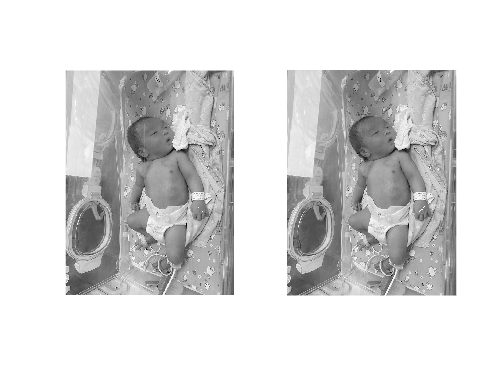

baby_square = insertMarker(baby_gray,[x,y],"*","color",'white','size',10);
baby_ncc = insertMarker(baby_gray,[x_ncc,y_ncc],"*","color",'white',"size",10);
subplot(1,2,1);imshow(baby_square);
subplot(1,2,2);imshow(baby_ncc);

    在这个任务中，我们使用了平方差与归一化互相关两种方法进行模板匹配，两种方式都是通过在目标图像中滑动来计算不同位置的的匹配度来完成模板匹配。平方差方法通过计算模板与目标图像之间的平方差，而归一化互相关则通过公式计算两者的相关性。

    从结果中我们发现，两种方法得到的最佳位置坐标都是（503，518），在当前情境中，两种方法都指向了同一个图像位置作为最佳匹配点。

    虽然本次任务中两种方法得到了相同的结果，但是在模板匹配任务中，我们应当考虑不同的情境选择不同的任务。

    （1）如果目标图像在整个区域内的图像对比度和光照条件一致时，应当选择**平方差方法，**因为它的计算更加简单，效率更高

    （2）如果对于处于不均匀光照范围内的图像，选择**归一化互相关方法**可能更为合适，因为它具有更强的鲁棒性，能够适应这些变化。

clear;
% RGB to gray
baby2 = imread("baby2.jpg");
baby2_gray = rgbtogray(baby2);

% Data type conversion
baby2_gray_double = double(baby2_gray);

% Gaussian Filter
sigma = 3;  Size = 5;
halfsize = (Size - 1)/2;
gaussion_filter = zeros(Size,Size);

for i = -halfsize:halfsize
    for j = -halfsize:halfsize
    x = j + halfsize + 1;
    y = i + halfsize + 1;
    exponent = exp(-(i^2 + j^2) / (2 * sigma^2));
    gaussion_filter(y, x) = (1 / (2 * pi * sigma^2)) * exponent;
    end
end
gaussion_filter = gaussion_filter / sum(gaussion_filter(:));

%padding
paddingSize = floor(Size / 2);
baby2_padded = padarray(baby2_gray_double, [paddingSize paddingSize], 'symmetric');

%conv
filteredImage = zeros(size(baby2_gray_double));

% 执行卷积操作
for i = 1:size(baby2_gray_double, 1)
    for j = 1:size(baby2_gray_double, 2)
        window = baby2_padded(i:i+Size-1, j:j+Size-1);
        value = sum(window(:) .* gaussion_filter(:));
        filteredImage(i, j) = value;
    end
end

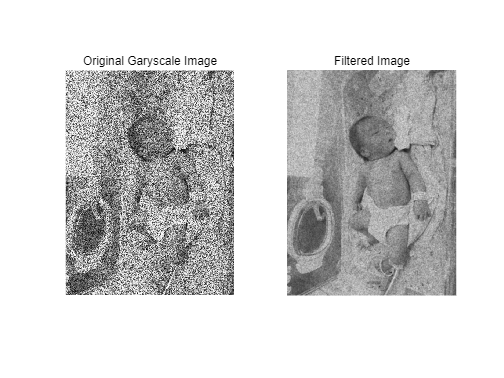

figure;
subplot(1,2,1), imshow(baby2_gray), title('Original Garyscale Image');
subplot(1,2,2), imshow(uint8(filteredImage)), title('Filtered Image');

function gray = rgbtogray(img)
    R = img(:,:,1);
    G = img(:,:,2);
    B = img(:,:,3);
    gray = 0.3*R+0.6*G+0.1*B;
end